Actc = [zeros(3,3),eye(3,3); zeros(3,3), zeros(3,3)];
Bctc = [zeros(3,3);eye(3,3)];


syms K1_p K2_p K3_p K1_v K2_v K3_v
Kmat1 = diag([K1_p, K2_p, K3_p]);
Kmat2 = diag([K1_v, K2_v, K3_v]);
K_test = [Kmat1,Kmat2];

ACL = Actc-Bctc*K_test

$$ACL = \left[\begin{array}{cccccc} 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ -K_{1,p} & 0 & 0 & -K_{1,v} & 0 & 0\\ 0 & -K_{2,p} & 0 & 0 & -K_{2,v} & 0\\ 0 & 0 & -K_{3,p} & 0 & 0 & -K_{3,v} \end{array}\right]$$

EIG_vals = eig(ACL)

$$EIG\_vals = \left[\begin{array}{c} -\frac{K_{1,v}}{2}-\frac{\sqrt{{K_{1,v}}^{2}-4\,K_{1,p}}}{2}\\ \frac{\sqrt{{K_{1,v}}^{2}-4\,K_{1,p}}}{2}-\frac{K_{1,v}}{2}\\ -\frac{K_{2,v}}{2}-\frac{\sqrt{{K_{2,v}}^{2}-4\,K_{2,p}}}{2}\\ \frac{\sqrt{{K_{2,v}}^{2}-4\,K_{2,p}}}{2}-\frac{K_{2,v}}{2}\\ -\frac{K_{3,v}}{2}-\frac{\sqrt{{K_{3,v}}^{2}-4\,K_{3,p}}}{2}\\ \frac{\sqrt{{K_{3,v}}^{2}-4\,K_{3,p}}}{2}-\frac{K_{3,v}}{2} \end{array}\right]$$


[Vcl,Dcl] = eig(ACL)

$$Vcl = \left[\begin{array}{cccccc} \frac{\frac{K_{1,v}}{2}+\frac{\sqrt{{K_{1,v}}^{2}-4\,K_{1,p}}}{2}}{K_{1,p}}-\frac{K_{1,v}}{K_{1,p}} & \frac{\frac{K_{1,v}}{2}-\frac{\sqrt{{K_{1,v}}^{2}-4\,K_{1,p}}}{2}}{K_{1,p}}-\frac{K_{1,v}}{K_{1,p}} & 0 & 0 & 0 & 0\\ 0 & 0 & \frac{\frac{K_{2,v}}{2}+\frac{\sqrt{{K_{2,v}}^{2}-4\,K_{2,p}}}{2}}{K_{2,p}}-\frac{K_{2,v}}{K_{2,p}} & \frac{\frac{K_{2,v}}{2}-\frac{\sqrt{{K_{2,v}}^{2}-4\,K_{2,p}}}{2}}{K_{2,p}}-\frac{K_{2,v}}{K_{2,p}} & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{\frac{K_{3,v}}{2}+\frac{\sqrt{{K_{3,v}}^{2}-4\,K_{3,p}}}{2}}{K_{3,p}}-\frac{K_{3,v}}{K_{3,p}} & \frac{\frac{K_{3,v}}{2}-\frac{\sqrt{{K_{3,v}}^{2}-4\,K_{3,p}}}{2}}{K_{3,p}}-\frac{K_{3,v}}{K_{3,p}}\\ 1 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 1 \end{array}\right]$$

$$Dcl = \left[\begin{array}{cccccc} -\frac{K_{1,v}}{2}-\frac{\sqrt{{K_{1,v}}^{2}-4\,K_{1,p}}}{2} & 0 & 0 & 0 & 0 & 0\\ 0 & \frac{\sqrt{{K_{1,v}}^{2}-4\,K_{1,p}}}{2}-\frac{K_{1,v}}{2} & 0 & 0 & 0 & 0\\ 0 & 0 & -\frac{K_{2,v}}{2}-\frac{\sqrt{{K_{2,v}}^{2}-4\,K_{2,p}}}{2} & 0 & 0 & 0\\ 0 & 0 & 0 & \frac{\sqrt{{K_{2,v}}^{2}-4\,K_{2,p}}}{2}-\frac{K_{2,v}}{2} & 0 & 0\\ 0 & 0 & 0 & 0 & -\frac{K_{3,v}}{2}-\frac{\sqrt{{K_{3,v}}^{2}-4\,K_{3,p}}}{2} & 0\\ 0 & 0 & 0 & 0 & 0 & \frac{\sqrt{{K_{3,v}}^{2}-4\,K_{3,p}}}{2}-\frac{K_{3,v}}{2} \end{array}\right]$$


k_set0 = ones(1,6);
EIG_set0 = double(subs(EIG_vals,[K1_p, K2_p, K3_p, K1_v, K2_v, K3_v], k_set0))

EIG_set0 =   -0.5000 - 0.8660i
  -0.5000 + 0.8660i
  -0.5000 - 0.8660i
  -0.5000 + 0.8660i
  -0.5000 - 0.8660i
  -0.5000 + 0.8660i



k_set1 = 10*ones(1,6);
EIG_set1 = double(subs(EIG_vals,[K1_p K2_p K3_p K1_v K2_v K3_v], k_set1))

EIG_set1 =    -8.8730
   -1.1270
   -8.8730
   -1.1270
   -8.8730
   -1.1270



k_set2 = [42, 12, 10, 13, 7, 7];
EIG_set2 = double(subs(EIG_vals,[K1_p K2_p K3_p K1_v K2_v K3_v], k_set2));

% Very nice results at the end of the simulation
k_set3 = [6, 4.83, 4.4, 4.9, 4.4, 4.2];
EIG_set3 = double(subs(EIG_vals,[K1_p K2_p K3_p K1_v K2_v K3_v], k_set3));

% System dinamics is too slow must increase the module of the poles
k_set4 = [0.021, 0.0143, 0.012, 0.29, 0.24, 0.22];
EIG_set4 = double(subs(EIG_vals,[K1_p K2_p K3_p K1_v K2_v K3_v], k_set4));

% Again more or less interesting results at the end of the simulation
k_set5 = [1.311, 1.2432, 1.2430, 2.29, 2.23, 2.23];
EIG_set5 = double(subs(EIG_vals,[K1_p K2_p K3_p K1_v K2_v K3_v], k_set5));

% Not usefull beacuse the sistem oscilates a lot
k_set6 = [182, 120, 12.1, 27, 22, 12.1];
EIG_set6 = double(subs(EIG_vals,[K1_p K2_p K3_p K1_v K2_v K3_v], k_set6));

% (!) Response is quite good at the end of the simulation
k_set7 = [20, 20, 20, 12, 12, 12];
EIG_set7 = double(subs(EIG_vals,[K1_p K2_p K3_p K1_v K2_v K3_v], k_set7));

% (!!) Amazing response inverting the gains
k_set8 = [12, 12, 12, 20, 20, 20];
EIG_set8 = double(subs(EIG_vals,[K1_p K2_p K3_p K1_v K2_v K3_v], k_set8));

% (!!) Again, pretty nice response
k_set9 = [7.5, 7.5, 7.5, 15.5, 15.5, 15.5];
EIG_set9 = double(subs(EIG_vals,[K1_p K2_p K3_p K1_v K2_v K3_v], k_set9));

% (!!!) Very good results still the system is too slow
k_set10 = [3, 3, 3, 15.2, 15.2, 15.2];
EIG_set10 = double(subs(EIG_vals,[K1_p K2_p K3_p K1_v K2_v K3_v],k_set10));

% (!!!) Results a bit better than Test 10
k_set11 = [12.2, 12.2, 3.8, 20.61, 20.61, 20.19];
EIG_set11 = double(subs(EIG_vals,[K1_p K2_p K3_p K1_v K2_v K3_v],k_set11));

% (!!!) Results pretty fit problem is that x has a bit of overshoot
k_set12 = [20, 12.2, 15, 20.61, 20.61, 20.19]

k_set12 =    20.0000   12.2000   15.0000   20.6100   20.6100   20.1900


EIG_set12 = double(subs(EIG_vals,[K1_p K2_p K3_p K1_v K2_v K3_v],k_set12))

EIG_set12 =   -19.5890
   -1.0210
  -20.0000
   -0.6100
  -19.4175
   -0.7725



% (!!!) VERY NICE RESPONSE BUT X STILL HAS OVERSHOOT
k_set13 = [20, 12.2, 15, 30, 20.61, 20.19]

k_set13 =    20.0000   12.2000   15.0000   30.0000   20.6100   20.1900


EIG_set13 = double(subs(EIG_vals,[K1_p K2_p K3_p K1_v K2_v K3_v],k_set13))

EIG_set13 =   -29.3178
   -0.6822
  -20.0000
   -0.6100
  -19.4175
   -0.7725



% (!!!!) Very nice results (!!!!)
k_set14 = [20, 12.2, 15, 40, 20.61, 20.19]

k_set14 =    20.0000   12.2000   15.0000   40.0000   20.6100   20.1900


EIG_set14 = double(subs(EIG_vals,[K1_p K2_p K3_p K1_v K2_v K3_v],k_set14))

EIG_set14 =   -39.4936
   -0.5064
  -20.0000
   -0.6100
  -19.4175
   -0.7725



% (!!!!) Achived to lower the overshoot of alpha
k_set15 = [20, 12.2, 30, 40, 20.61, 40]

k_set15 =    20.0000   12.2000   30.0000   40.0000   20.6100   40.0000


EIG_set15 = double(subs(EIG_vals,[K1_p K2_p K3_p K1_v K2_v K3_v],k_set15))

EIG_set15 =   -39.4936
   -0.5064
  -20.0000
   -0.6100
  -39.2354
   -0.7646



% (*!*) Amazing response but even with all this high gains alpha has a bit
% of overshoot
k_set16 = [20, 12.2, 200, 40, 20.61, 220]

k_set16 =    20.0000   12.2000  200.0000   40.0000   20.6100  220.0000


EIG_set16 = double(subs(EIG_vals,[K1_p K2_p K3_p K1_v K2_v K3_v],k_set16))

EIG_set16 =   -39.4936
   -0.5064
  -20.0000
   -0.6100
 -219.0871
   -0.9129


## DCGain

% Dc gain of the sistem for X and Y with k_set16

% First create the system
ACL_fun = matlabFunction(ACL);

ACL_set16 = ACL_fun(k_set16(1), k_set16(2), k_set16(3), k_set16(4), k_set16(5), k_set16(6))

ACL_set16 =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
  -20.0000         0         0  -40.0000         0         0
         0  -12.2000         0         0  -20.6100         0
         0         0 -200.0000         0         0 -220.0000



BCL = [zeros(3,3);eye(3)];

DCL = zeros(6,3);

% Output for X
CCL_X = diag([1,1,1,1,1,1]); 

sys_set16_X = ss(ACL_set16,BCL,CCL_X,DCL)

sys_set16_X =
 
  A = 
           x1      x2      x3      x4      x5      x6
   x1       0       0       0       1       0       0
   x2       0       0       0       0       1       0
   x3       0       0       0       0       0       1
   x4     -20       0       0     -40       0       0
   x5       0   -12.2       0       0  -20.61       0
   x6       0       0    -200       0       0    -220
 
  B = 
       u1  u2  u3
   x1   0   0   0
   x2   0   0   0
   x3   0   0   0
   x4   1   0   0
   x5   0   1   0
   x6   0   0   1
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
   y5   0   0   0   0   1   0
   y6   0   0   0   0   0   1
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
   y3   0   0   0
   y4   0   0   0
   y5   0   0   0
   y6   0   0   0
 
Continuous-time state-space model.




K_X = dcgain(sys_set16_X)

K_X =     0.0500         0         0
         0    0.0820         0
         0         0    0.0050
         0         0         0
         0         0         0
         0         0         0


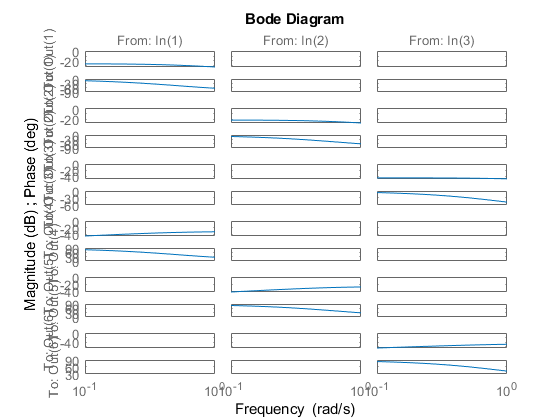

w = logspace(-1,0);
bode(sys_set16_X,w)

[mag, phase] = bode(sys_set16_X,0.3)

mag =     0.0430         0         0
         0    0.0735         0
         0         0    0.0048
    0.0129         0         0
         0    0.0221         0
         0         0    0.0014


phase =   -31.0779         0         0
         0  -27.0475         0
         0         0  -18.2706
   58.9221         0         0
         0   62.9525         0
         0         0   71.7294


As a conclusion we can assume that the dynamics of the lineal system anole is little diferent thtat the whole system and thus the anly way to know a specific gain for specifc frequency is cheking it manually.